# Dynamic Mode Decomposition

This file contains demonstrations of Dynamic Mode Decomposition (DMD) applied to analytical systems and real data. The DMD algorithm is perfomed in the file` DMD.m`

**References:**

- Kutz, J. Nathan, et al. *Dynamic mode decomposition: data-driven modeling of complex systems*. Society for Industrial and Applied Mathematics, 2016: [https://epubs.siam.org/doi/book/10.1137/1.9781611974508](https://epubs.siam.org/doi/book/10.1137/1.9781611974508)

- DMD Course Notes: [https://drive.google.com/file/d/1t_b6HPv6v9C98oHqFt5J0mTnjG36xaej/view](https://drive.google.com/file/d/1t_b6HPv6v9C98oHqFt5J0mTnjG36xaej/view)

- Ball Bearing Data: [https://engineering.case.edu/bearingdatacenter](https://engineering.case.edu/bearingdatacenter)

## Analytical Systems

In this section, a systems of ODE's is solved to generate time series data. DMD is applied to the solutions of the ODE's and the DMD modes an eigenvalues are shown in the plots below. The eigenvalues of the transision matrix can be correlated with the steady state solutions to the systems.

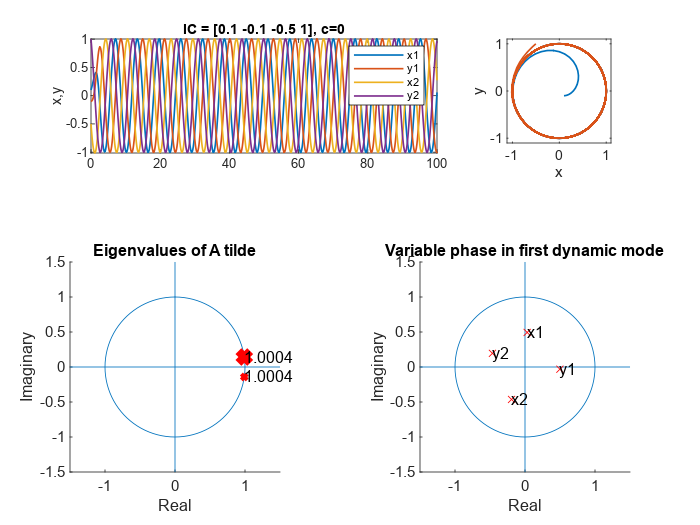

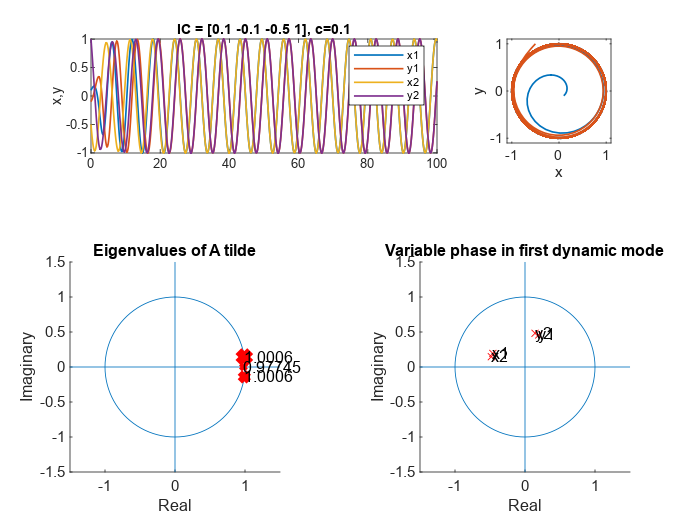

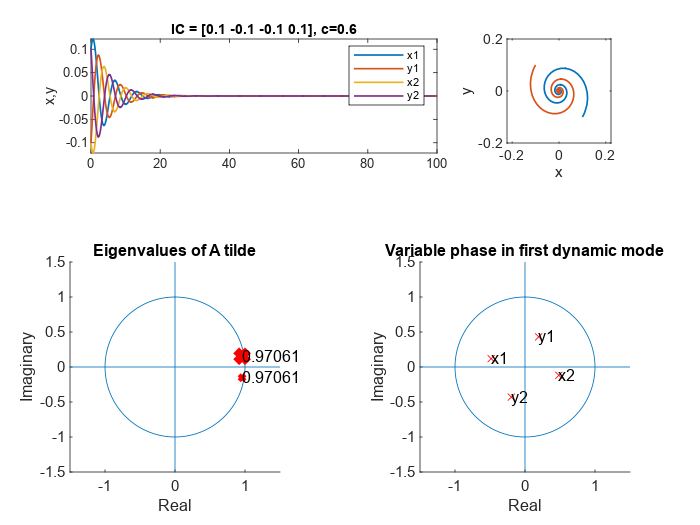

t_span = 100;
e=0.01;
varnames = {'x1','y1','x2','y2'};

for z = 1:3
    % Coupling parameter and initial conditions
    if z == 1
        c = 0.0;
        init = [.1, -.1, -.5, 1];
    elseif z == 2
        c = 0.1;
        init = [.1, -.1, -.5, 1];
    elseif z == 3
        c = 0.6;
        init = [.1, -.1, -.1, .1];
    end
    
    % ODE solver
    [t, y_eq] = ode45(@(t,y) dmd_eq(t,y,c), [0,t_span], init);%, odeopts);

    % function plot over time
    h = figure;
    subplot(3,3,[1,2])
    plot(t, y_eq(:,:),'LineWidth',1)
    ylabel('x,y')
    legend(varnames)
    title(['IC = [',num2str(init(1)),' ',num2str(init(2)),' ',num2str(init(3)),...
            ' ',num2str(init(4)),'], c=',num2str(c)])
    xlim([0, t_span])

    % phase coupling plot
    subplot(333)
    plot(y_eq(:,1), y_eq(:,2),'LineWidth',1);hold on
    plot(y_eq(:,3), y_eq(:,4),'LineWidth',1)
    xlabel('x')
    ylabel('y')
    axis square
    buff = .1;
    axis([min([y_eq(:,1);y_eq(:,3)])-buff max([y_eq(:,1);y_eq(:,3)])+buff...
        min([y_eq(:,2);y_eq(:,4)])-buff max([y_eq(:,2);y_eq(:,4)])+buff])

    % DMD
    thresh = .9;
    deltaT = mean(diff(t));
    p = 20;

    Output = DMD(y_eq',[],thresh);

    for i = 1:Output.DMD.r
        emp_omega_r_phi(i,1) = imag(log(Output.DMD.D(i))/deltaT)/(2*pi);
        emp_omega_r_phi(i,2) = abs(Output.DMD.D(i));
        emp_omega_r_phi(i,3) = atan2(imag(Output.DMD.D(i)),real(Output.DMD.D(i)))*(180/pi);
    end

    % eigen value spectrum of A tilde
    figure(h)
    subplot('position',[.05 .1 .4 .4])
    D = Output.DMD.D;
    D_plot = zeros(length(D),2);
    for i = 1:length(D)
        D_plot(i,1) = real(D(i));
        D_plot(i,2) = imag(D(i));
    end

    M_size = sort(1:Output.DMD.r,'descend');
    M_size_norm = normalize_var(M_size,5,10);

    circle(0,0,1);hold on
    line([0 0],[-2 2])
    line([-2 2], [0 0])
    for i = 1:length(D)
        plot(D_plot(i,1), D_plot(i,2), 'rx','MarkerSize', M_size_norm(i),'LineWidth', M_size_norm(i)/2)
        text(D_plot(i,1),D_plot(i,2),num2str(norm(D_plot(i,:))))
    end
    xlim([-1.5 1.5])
    ylim([-1.5 1.5])
    axis square
    xlabel('Real')
    ylabel('Imaginary')
    title('Eigenvalues of A tilde')

    % Mode selection
    for i = 1:Output.DMD.r
        x(i) = abs(emp_omega_r_phi(i,1));
        y(i) = (abs(Output.DMD.D(i))^p)*norm(Output.DMD.DynamicModes(:,i));
    end

    % phase of variables to first dynamic mode
    figure(h)
    subplot('position',[.55 .1 .4 .4])
    circle(0,0,1);hold on
    line([0 0],[-2 2])
    line([-2 2], [0 0])
    plot(Output.DMD.DynamicModes(:,1),'rx')
    for i = 1:length(Output.DMD.DynamicModes(:,1))
        text(real(Output.DMD.DynamicModes(i,1)),imag(Output.DMD.DynamicModes(i,1)),varnames{i})
    end
    xlim([-1.5 1.5])
    ylim([-1.5 1.5])
    axis square
    xlabel('Real')
    ylabel('Imaginary')
    title('Variable phase in first dynamic mode')
end

## Ball Bearings

Vibration signals were collected from both endsof a ball bearing joint and are analyzed in this section below. The Ball Bearing Data Center is a database containing time series vibration signals from bearing joints that are used in fault detection studied. The data below contains two time series signals captured in parallel.

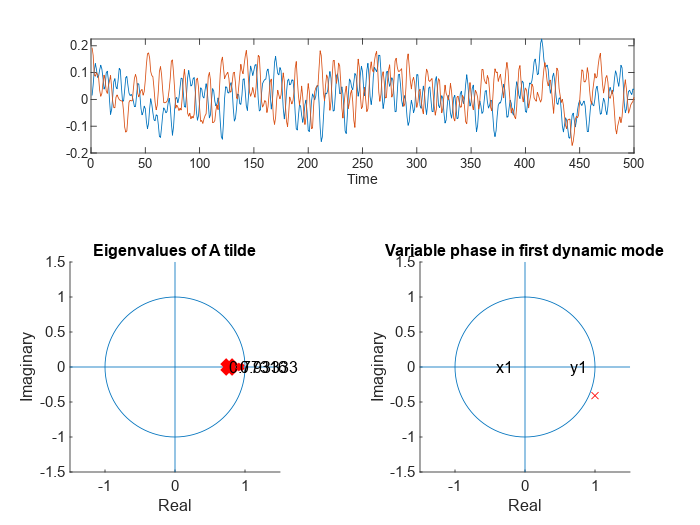

load('data/N_3.mat')
D = [X100_DE_time X100_FE_time]';
clear X100_DE_time X100_FE_time X100RPM
varnames = {'x1','y1','x2','y2'};

thresh = 0.9;
Output = DMD(D,[],thresh);
h = figure;
subplot(3,3,[1,2,3]);
plot(D(:,1:500)');
xlabel('Time');
subplot('position',[.05 .1 .4 .4])
D = Output.DMD.D;
D_plot = zeros(length(D),2);
for i = 1:length(D)
    D_plot(i,1) = real(D(i));
    D_plot(i,2) = imag(D(i));
end

M_size = sort(1:Output.DMD.r,'descend');
M_size_norm = normalize_var(M_size,5,10);

circle(0,0,1);hold on
line([0 0],[-2 2])
line([-2 2], [0 0])
for i = 1:length(D)
    plot(D_plot(i,1), D_plot(i,2), 'rx','MarkerSize', M_size_norm(i),'LineWidth', M_size_norm(i)/2)
    text(D_plot(i,1),D_plot(i,2),num2str(norm(D_plot(i,:))))
end
xlim([-1.5 1.5])
ylim([-1.5 1.5])
axis square
xlabel('Real')
ylabel('Imaginary')
title('Eigenvalues of A tilde')
    subplot('position',[.55 .1 .4 .4])
    circle(0,0,1);hold on
    line([0 0],[-2 2])
    line([-2 2], [0 0])
    plot(Output.DMD.DynamicModes(:,1),'rx')
for i = 1:length(Output.DMD.DynamicModes(:,1))
    text(real(Output.DMD.DynamicModes(i,1)),imag(Output.DMD.DynamicModes(i,1)),varnames{i})
end
xlim([-1.5 1.5])
ylim([-1.5 1.5])
axis square
xlabel('Real')
ylabel('Imaginary')
title('Variable phase in first dynamic mode')

## ECG

In this section a 12-lead ECG signal is analyzed with DMD. The data containes informatino from 12 sensors captured throughout time. The increased number of sensors gives more DMD modes.

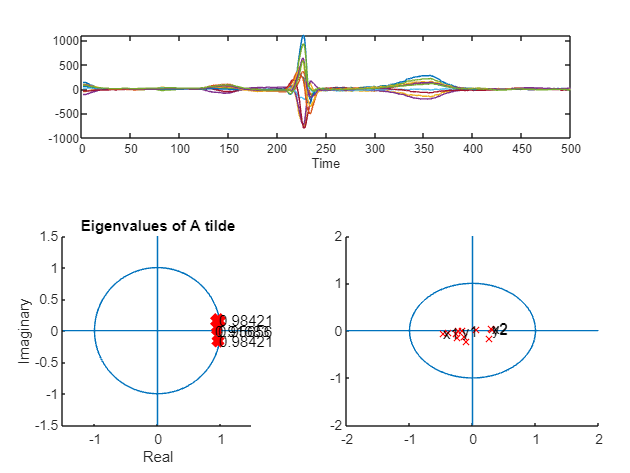

Index exceeds the number of array elements. Index must not exceed 4.

load('data/ECG1.mat')
D = val;

thresh = 0.9;
Output = DMD(D,[],thresh);
h = figure;
subplot(3,3,[1,2,3]);
plot(D(:,1:500)');
xlabel('Time');
subplot('position',[.05 .1 .4 .4])
D = Output.DMD.D;
D_plot = zeros(length(D),2);
for i = 1:length(D)
    D_plot(i,1) = real(D(i));
    D_plot(i,2) = imag(D(i));
end

M_size = sort(1:Output.DMD.r,'descend');
M_size_norm = normalize_var(M_size,5,10);

circle(0,0,1);hold on
line([0 0],[-2 2])
line([-2 2], [0 0])
for i = 1:length(D)
    plot(D_plot(i,1), D_plot(i,2), 'rx','MarkerSize', M_size_norm(i),'LineWidth', M_size_norm(i)/2)
    text(D_plot(i,1),D_plot(i,2),num2str(norm(D_plot(i,:))))
end
xlim([-1.5 1.5])
ylim([-1.5 1.5])
axis square
xlabel('Real')
ylabel('Imaginary')
title('Eigenvalues of A tilde')
    subplot('position',[.55 .1 .4 .4])
    circle(0,0,1);hold on
    line([0 0],[-2 2])
    line([-2 2], [0 0])
    plot(Output.DMD.DynamicModes(:,1),'rx')
for i = 1:length(Output.DMD.DynamicModes(:,1))
    text(real(Output.DMD.DynamicModes(i,1)),imag(Output.DMD.DynamicModes(i,1)),varnames{i})
end